# Coupled PDE's

## Initialization of MATLAB

clear variables; close all; clc
beamerFlag = 1; % Beamer Export or document export
AR = 1.618;
if beamerFlag == 1 % width=12.5cm, height=6.5cm (w/o title); width=12.5cm, height=5.5cm (w title)
    width = 12.5; height = width/AR;
elseif beamerFlag == 0
    width = 12; height = width/AR;
end

#### Full order model


$$u_t = a u_{xx}+\alpha(v-u)\\
v_t = b v_{xx}+\beta(u-v)\\
u(0,t) = u_L, u(1,t) = u_R\\
v(0,t) = v_L, v(1,t) = v_R$$


% Constants
a = 0.1; b = 1; alpha = 0.15; beta = 1; U = 0.25; V = 0.15;
% Boundary Conditions
uL = 0; uR = 1; vL = 0.1; vR = 0.2;
% Solver settings (common)
Nx = 150; x = linspace(0,1,Nx); dx = x(2)-x(1); x = x';
t = 0.5; dt = 0.8*dx^2/(2*max(a,b)); Nt = length(0:dt:t);
% t = 0.5; Nt = 50000; D2 = linspace(0,0.5,Nt); dt = D2(2)-D2(1);
D2 = spdiags([ones(Nx,1) -2*ones(Nx,1) ones(Nx,1)], [-1 0 1], Nx, Nx) / dx^2;
D2(1,:) = 0; D2(end,:) = 0;
D2(1,1) = 1; D2(end,end) = 1;
% Initial Conditions
uI = @(x) uR*x + U*sin(pi*x) - uL*(x - 1);
vI = @(x) vR*x + V*sin(pi*x) - vL*(x - 1);
% Method of manufacturing solutions Refer, MMS_v2
Fu = @(x,t) alpha*(uR*x - vR*x - uL*(x - 1) + vL*(x - 1) + U*cos(2*pi*t)*sin(pi*x) - V*cos(2*pi*t)*sin(pi*x)) - 2*U*pi*sin(2*pi*t)*sin(pi*x) + U*a*pi^2*cos(2*pi*t)*sin(pi*x);
Fv = @ (x,t) V*b*pi^2*cos(2*pi*t)*sin(pi*x) - 2*V*pi*sin(2*pi*t)*sin(pi*x) - beta*(uR*x - vR*x - uL*(x - 1) + vL*(x - 1) + U*cos(2*pi*t)*sin(pi*x) - V*cos(2*pi*t)*sin(pi*x));
uVal = uR*x - uL*(x - 1) + U*cos(2*pi*t)*sin(pi*x);
vVal = vR*x - vL*(x - 1) + V*cos(2*pi*t)*sin(pi*x);
% Solving FOM for Validation (Perfect)
tic;
[uFOM,vFOM] = solveFOMv4(Nx,Nt,dt,uI,vI,uL, uR, vL, vR, D2, alpha, beta, a, b, Fu, Fv);
elapsedFOM = toc;
errFOM = (norm([uFOM(:,end),vFOM(:,end)],'fro')-norm([uVal,vVal],'fro'))*100/norm([uVal,vVal],'fro');
% figure;
% plot(uFOM(:,end)); hold on; plot(uVal,"--")
% figure;
% plot(vFOM(:,end)); hold on; plot(vVal,"--")

#### Reduced Order Model

Idea is to compare the ROM with FOM

% Reduced order model
uBC = @(x)(uL*(1 - x) + uR.*x);
vBC = @(x)(vL*(1 - x) + vR.*x);
tic;
[uROM,vROM,~,~] = solveROMv4(uFOM,vFOM,uBC,vBC,D2,a,b,alpha,beta,Nt,dt,Fu,Fv,x);
elapsedROM = toc;
errROM = (norm([uROM,vROM],'fro')-norm([uFOM,vFOM],'fro'))*100/norm([uFOM,vFOM],'fro');
% figure;
% subplot(1,2,1); plot(x,uFOM(:,end),'k',x,uROM(:,end),'r--',x(1,1:20:end),uVal(1,1:20:end),"k*"); title('u');
% subplot(1,2,2); plot(x,vFOM(:,end),'k',x,vROM(:,end),'r--',x(1,1:20:end),vVal(1,1:20:end),"k*"); title('v');
% legend('FOM','ROM',"True");

#### Inverse Problem (FOM)

Now as the first step, based on the given u, v we will find the value of alpha through FOM, ROM

% uTrue = uFOM(:,end); vTrue = vFOM(:,end); % Given Data
% aTrue = 0.1; bTrue = 1;
% r = (sqrt(5)-1)/2;
% aInv = 0.1935; bInv = 0.7; % Initial guess
% tol = 1e-3;
% tic;
% aPrev = aInv; 
% bPrev = bInv;
% for i = 1:5
%     % --- Golden search on 'a' keeping 'b' fixed ---
%     a1 = 0; a2 = 0.5;
%     iterA = 0;
%     while true
%         iterA = iterA + 1;
%         aL = a2 - r*(a2 - a1);
%         aR = a1 + r*(a2 - a1);
%         JL = goldenLossFOMv4(Nx,Nt,dt,uI,vI,uL,uR,vL,vR,D2,alpha,beta,aL,bInv,Fu,Fv,uTrue,vTrue);
%         JR = goldenLossFOMv4(Nx,Nt,dt,uI,vI,uL,uR,vL,vR,D2,alpha,beta,aR,bInv,Fu,Fv,uTrue,vTrue);
%         if JL < JR
%             a2 = aR;
%         else
%             a1 = aL;
%         end
% 
%         apInv = (a1 + a2)/2;
%         if abs(apInv - aInv) < tol
%             aInv = apInv;
%             break;
%         end
%         aInv = apInv;
%     end
% 
%     --- Golden search on 'b' keeping 'a' fixed ---
%     b1 = 0; b2 = 2;
%     iterB = 0;
%     while true
%         iterB = iterB + 1;
%         bL = b2 - r*(b2 - b1);
%         bR = b1 + r*(b2 - b1);
% 
%         JL = goldenLossFOMv4(Nx,Nt,dt,uI,vI,uL,uR,vL,vR,D2,alpha,beta,aInv,bL,Fu,Fv,uTrue,vTrue);
%         JR = goldenLossFOMv4(Nx,Nt,dt,uI,vI,uL,uR,vL,vR,D2,alpha,beta,aInv,bR,Fu,Fv,uTrue,vTrue);
% 
%         if JL < JR
%             b2 = bR;
%         else
%             b1 = bL;
%         end
% 
%         bpInv = (b1 + b2)/2;
%         if abs(bpInv - bInv) < tol
%             bInv = bpInv;
%             break;
%         end
%         bInv = bpInv;
% 
%     end
%     if abs(aInv - aPrev) < tol && abs(bInv - bPrev)< tol
%         break;
%     end
%     aPrev = aInv;
%     bPrev = bInv;
% end
% 
% elapsedFOMInv = toc;

#### Gradients Visualization-FOM: Brute Force Optimization

% tic
% aList = linspace(0,2,10);
% bList = linspace(0,2,10);
% JMat = zeros(length(aList), length(bList));
% for i = 1:length(aList)
%     for j = 1:length(bList)
%         JMat(i,j) = goldenLossFOMv4(Nx,Nt,dt,uI,vI,uL,uR,vL,vR,D2,alpha,beta,aList(i),bList(j),Fu,Fv,uFOM(:,end),vFOM(:,end));
%     end
% end
% elapsedBruteFOM = toc;

#### Inverse Problem (ROM)

% nSnap = 2;
% aInv = 0.1935; bInv = 0.7; % Initial guess
% uTrue = uFOM(:,round(linspace(1, Nt, nSnap))); 
% vTrue = vFOM(:,round(linspace(1, Nt, nSnap))); % Given Data
% tic;
% aPrev = aInv; 
% bPrev = bInv;
% for i = 1:5
%     % --- Golden search on 'a' keeping 'b' fixed ---
%     a1 = 0; a2 = 0.5;
%     iterA = 0;
%     while true
%         iterA = iterA + 1;
%         aL = a2 - r*(a2 - a1);
%         aR = a1 + r*(a2 - a1);
%         JL = goldenLossROMv4(uTrue,vTrue,uBC,vBC,D2,aL,bInv,alpha,beta,Nt,dt,Fu,Fv,x);
%         JR = goldenLossROMv4(uTrue,vTrue,uBC,vBC,D2,aR,bInv,alpha,beta,Nt,dt,Fu,Fv,x);
%         if JL < JR
%             a2 = aR;
%         else
%             a1 = aL;
%         end
% 
%         apInv = (a1 + a2)/2;
%         if abs(apInv - aInv) < tol
%             aInv = apInv;
%             break;
%         end
%         aInv = apInv;
%     end
% 
%     % --- Golden search on 'b' keeping 'a' fixed ---
%     b1 = 0; b2 = 2;
%     iterB = 0;
%     while true
%         iterB = iterB + 1;
%         bL = b2 - r*(b2 - b1);
%         bR = b1 + r*(b2 - b1);
% 
%         JL = goldenLossROMv4(uTrue,vTrue,uBC,vBC,D2,aInv,bL,alpha,beta,Nt,dt,Fu,Fv,x);
%         JR = goldenLossROMv4(uTrue,vTrue,uBC,vBC,D2,aInv,bR,alpha,beta,Nt,dt,Fu,Fv,x);
% 
%         if JL < JR
%             b2 = bR;
%         else
%             b1 = bL;
%         end
%         bpInv = (b1 + b2)/2;
%         if abs(bpInv - bInv) < tol
%             bInv = bpInv;
%             break;
%         end
%         bInv = bpInv;
% 
%     end
%     if abs(aInv - aPrev) < tol && abs(bInv - bPrev)< tol
%         break;
%     end
%     aPrev = aInv;
%     bPrev = bInv;
% end
% elapsedROMInv = toc;

#### Gradient Visualization- ROM

% tic
% aList = linspace(0,2,10);
% bList = linspace(0,2,10);
% JMat = zeros(length(aList), length(bList));
% 
% for i = 1:length(aList)
%     for j = 1:length(bList)
%         JMat(i,j) = goldenLossROMv4(uFOM(:,end),vFOM(:,end),uBC,vBC,D2,aList(i),bList(j),alpha,beta,Nt,dt,Fu,Fv,x);
%     end
% end
% elapsedBruteROM = toc;

#### Computational Complexity for inverse problem

% % NxList, T_FOM, T_ROM are your data vectors (column)
% NxList = [50 60 70 90 120 150 ]';
% T_FOM  = [12.6204115 21.4381504 29.4724452 65.8561271 1.46E+02 2.67E+02]';
% T_ROM  = [11.0606075 19.2942671 27.8392133 58.1853926 1.30E+02 3.05E+02]';
% 
% % Fit log-log: log(T) = log(c) + p*log(N)
% pF = polyfit(log(NxList), log(T_FOM), 1);
% pR = polyfit(log(NxList), log(T_ROM), 1);
% pF_exp = pF(1); cF = exp(pF(2));
% pR_exp = pR(1); cR = exp(pR(2));
% 
% fprintf('FOM: p=%.4f, c=%.4e\n', pF_exp, cF);
% fprintf('ROM: p=%.4f, c=%.4e\n', pR_exp, cR);
% 
% % Cross-over (if exponents differ significantly)
% if abs(pF_exp - pR_exp) > 1e-6
%     Ncross = (cR / cF)^(1/(pF_exp - pR_exp));
%     fprintf('Cross-over N*: %.3g\n', Ncross);
% else
%     fprintf('Exponents nearly equal — cross-over governed by prefactor ratio.\n');
%     Ncross = NaN;
% end
% 
% % Plot data and fits
% Nplot = linspace(min(NxList), 1e4, 200);
% TFfit = cF .* Nplot.^pF_exp;
% TRfit = cR .* Nplot.^pR_exp;
% figure; loglog(NxList, T_FOM, 'o', NxList, T_ROM, 's'); hold on;
% loglog(Nplot, TFfit, '-', 'LineWidth',1.5); loglog(Nplot, TRfit, '--', 'LineWidth',1.5);
% legend('FOM data','ROM data','FOM fit','ROM fit','Location','NorthWest');
% xlabel('N_x'); ylabel('Time (s)'); grid on;
% if ~isnan(Ncross)
%     yl = ylim; plot([Ncross Ncross], yl, ':k'); text(Ncross, yl(2)/2, sprintf('N^*=%.2e',Ncross));
% end

% Nx	FOM Brute	ROM Brute	FOM	ROM
% 50	11.8605729	8.6858568	0.2282714	0.232835
% 75	33.5038741	28.0472998	0.478491	0.50864
% 100	76.1205137	63.3283546	0.9815167	1.3064929
% 125	1.31E+02	1.15E+02	1.8420063	2.0018612
% 150	2.18E+02	1.96E+02	2.2035337	3.2269657
% 200	444.4944631	404.4184783	6.1480123	5.6794582


## Plots

% R4v1
% Validation and corresponding plot of FOM, ROM

% Solver common settings
Nx = 150; Lx = 1; x = linspace(0, Lx, Nx)'; dx = x(2)-x(1);
t = 0.5;
D2 = spdiags([ones(Nx,1) -2*ones(Nx,1) ones(Nx,1)], [-1 0 1], Nx, Nx) / dx^2;
D2(1,:) = 0; D2(end,:) = 0; D2(1,1) = 1; D2(end,end) = 1;

% Boundary conditions
uL = 0; uR = 1; vL = 0.1; vR = 0.2;

% 3 sets of (a,b,U,V)
paramSets = [
    0.05  0.1  0.25  0.15;  % Case 1
    0.2   0.5  0.30  0.10;  % Case 2
    1.0   0.8  0.10  0.25]; % Case 3

% Predefine figure
figure('Units','normalized','Position',[0.1 0.1 0.7 0.75]);
tiledlayout(3,2, 'TileSpacing','compact', 'Padding','compact');

for k = 1:3
    a = paramSets(k,1); b = paramSets(k,2);
    U = paramSets(k,3); V = paramSets(k,4);
    alpha = 0.15; beta = 1;

    % Time step and total steps
    dt = 0.8*dx^2/(2*max(a,b)); 
    Nt = length(0:dt:t);

    % Manufactured solutions
    uI = @(x) uR*x + U*sin(pi*x) - uL*(x - 1);
    vI = @(x) vR*x + V*sin(pi*x) - vL*(x - 1);
    Fu = @(x,t) alpha*(uR*x - vR*x - uL*(x - 1) + vL*(x - 1) + U*cos(2*pi*t)*sin(pi*x) - V*cos(2*pi*t)*sin(pi*x)) ...
                - 2*U*pi*sin(2*pi*t)*sin(pi*x) + U*a*pi^2*cos(2*pi*t)*sin(pi*x);
    Fv = @(x,t) V*b*pi^2*cos(2*pi*t)*sin(pi*x) - 2*V*pi*sin(2*pi*t)*sin(pi*x) ...
                - beta*(uR*x - vR*x - uL*(x - 1) + vL*(x - 1) + U*cos(2*pi*t)*sin(pi*x) - V*cos(2*pi*t)*sin(pi*x));

    % Analytical
    uVal = uR*x - uL*(x - 1) + U*cos(2*pi*t)*sin(pi*x);
    vVal = vR*x - vL*(x - 1) + V*cos(2*pi*t)*sin(pi*x);

    % --- FOM ---
    [uFOM,vFOM] = solveFOMv4(Nx,Nt,dt,uI,vI,uL,uR,vL,vR,D2,alpha,beta,a,b,Fu,Fv);

    % --- ROM ---
    uBC = @(x)(uL*(1 - x) + uR.*x);
    vBC = @(x)(vL*(1 - x) + vR.*x);
    [uROM,vROM,~,~] = solveROMv4(uFOM,vFOM,uBC,vBC,D2,a,b,alpha,beta,Nt,dt,Fu,Fv,x);

    % --- Compute errors ---
    errFOM(k) = norm([uFOM(:,end),vFOM(:,end)] - [uVal,vVal],'fro')/norm([uVal,vVal],'fro')*100;
    errROM(k) = norm([uROM(:,end),vROM(:,end)] - [uVal, vVal],'fro')/norm([uVal, vVal],'fro')*100;

    % --- Plot u ---
    nexttile;
    plot(x, uFOM(:,end), 'r-', 'LineWidth', 1.3, 'DisplayName', 'FOM');
    hold on;
    plot(x, uROM(:,end), 'b--', 'LineWidth', 1.3, 'DisplayName', 'ROM');
    plot(x(1:7:end), uVal(1:7:end), 'k*', 'DisplayName', 'Analytical');
    xlabel('$x$', 'Interpreter','latex');
    ylabel('$u(x)$', 'Interpreter','latex');
    % title(sprintf('Case %d: a=%.2f, b=%.2f, U=%.2f, V=%.2f',k,a,b,U,V), 'Interpreter','latex');
    % legend('Location','north');
    grid on;

    % --- Plot v ---
    nexttile;
    plot(x, vFOM(:,end), 'r-', 'LineWidth', 1.3, 'DisplayName', 'FOM');
    hold on;
    plot(x, vROM(:,end), 'b--', 'LineWidth', 1.3, 'DisplayName', 'ROM');
    plot(x(1:7:end), vVal(1:7:end), 'k*', 'DisplayName', 'Analytical');
    xlabel('$x$', 'Interpreter','latex');
    ylabel('$v(x)$', 'Interpreter','latex');
    % legend('Location','north');
    ax = gca;
    ax.YAxisLocation = 'right';  % Move y-axis to right side
    grid on;

    fprintf('Case %d: errFOM = %.3f%%, errROM = %.3f%%\n', k, errFOM, errROM);
end

Case 1: errFOM = 0.000%, errROM = 0.000%
Case 2: errFOM = 0.000%, errROM = 0.000%
Case 9.584802e-05: errFOM = 0.000%, errROM = Case 3: errFOM = 0.000%, errROM = 0.000%
Case 8.885957e-04: errFOM = 0.000%, errROM = 0.000%
Case 8.311478e-04: errFOM = 

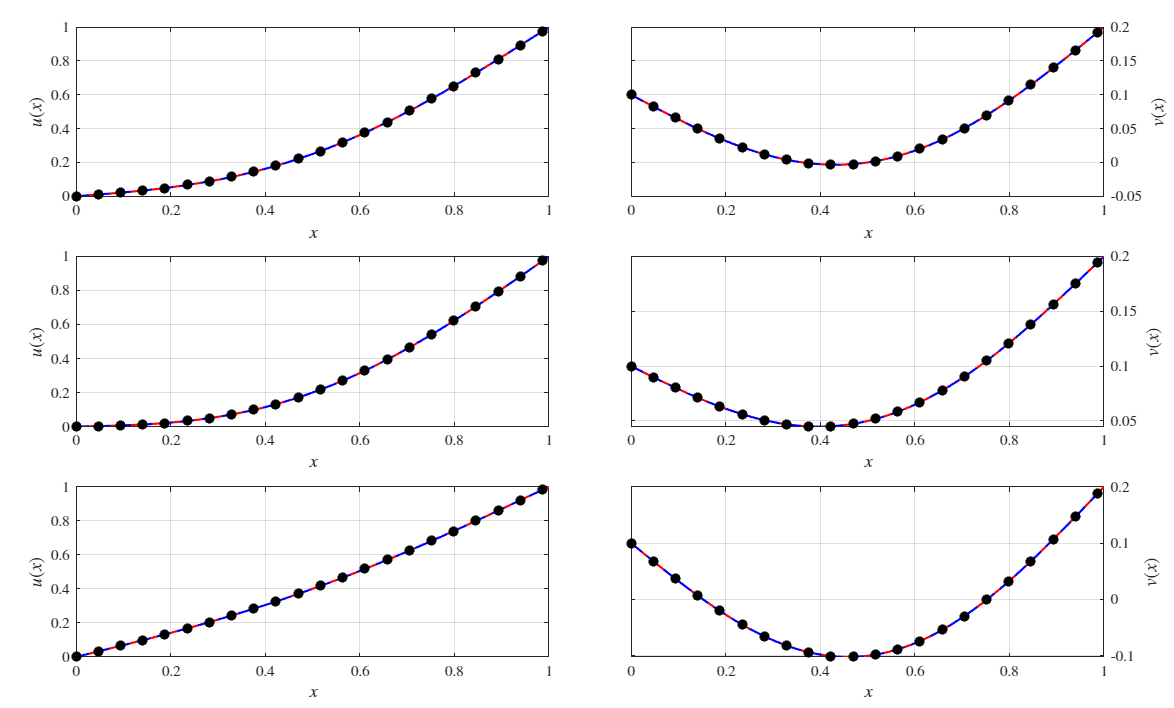

matlab2tikz('Plots/R4f1.tex','width', sprintf('%.2fcm', width),'height', sprintf('%.2fcm', height), 'showInfo', false);

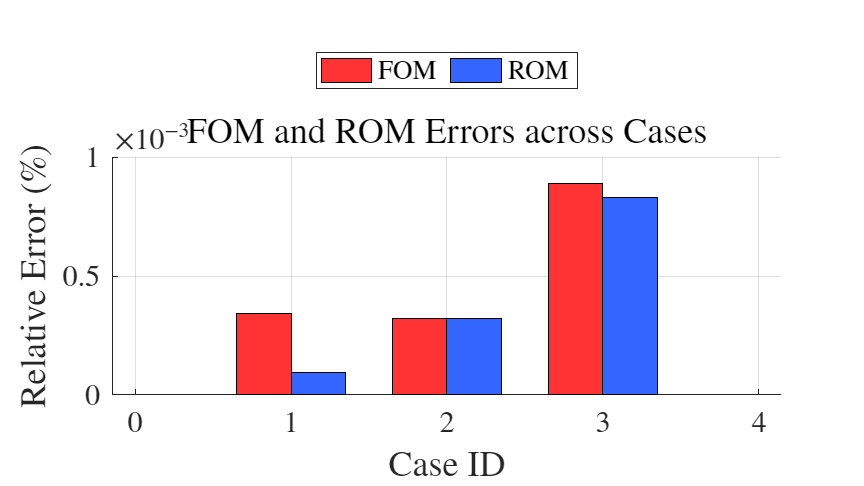

% R4f2
% Error comparison of ROM, FOM with analytical data
figure('Units','normalized','Position',[0.25 0.25 0.45 0.45]);
caseIDs = 1:3;
barWidth = 0.35;

% Bar chart with side-by-side FOM and ROM errors
hold on;
b1 = bar(caseIDs - barWidth/2, errFOM, barWidth, 'FaceColor', [1 0.2 0.2], 'DisplayName', 'FOM');
b2 = bar(caseIDs + barWidth/2, errROM, barWidth, 'FaceColor', [0.2 0.4 1], 'DisplayName', 'ROM');
hold off;

% Axis and labels
xlabel('Case ID', 'Interpreter','latex');
ylabel('Relative Error (\%)', 'Interpreter','latex');
title('FOM and ROM Errors across Cases', 'Interpreter','latex');
legend('Location','northoutside','Orientation','horizontal');
grid on;

% Annotate bars with exact values
for k = 1:length(caseIDs)
    text(caseIDs(k)-barWidth/2, errFOM(k)+0.1, sprintf('%.2f', errFOM(k)), ...
        'HorizontalAlignment','center', 'FontSize', 9, 'Color', 'k');
    text(caseIDs(k)+barWidth/2, errROM(k)+0.1, sprintf('%.2f', errROM(k)), ...
        'HorizontalAlignment','center', 'FontSize', 9, 'Color', 'k');
end

matlab2tikz('Plots/R4f2.tex','width', sprintf('%.2fcm', width),'height', sprintf('%.2fcm', height), 'showInfo', false);

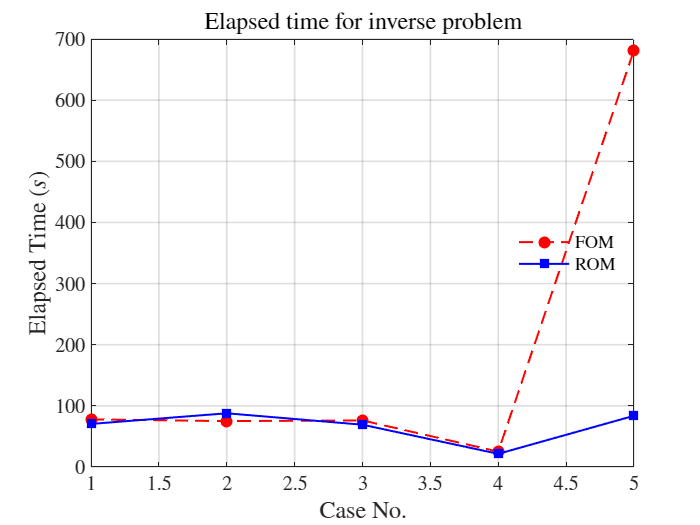

% R4f4,5
% Performance plot of golden search

for k = 1:5
    a = 0.1+rand*0.9; b = 0.1+rand*1.9;
    % Constants
    alpha = 0.15; beta = 1; U = 0.25; V = 0.15;
    % Boundary Conditions
    uL = 0; uR = 1; vL = 0.1; vR = 0.2;
    % Solver settings (common)
    Nx = 75; x = linspace(0,1,Nx); dx = x(2)-x(1); x = x';
    t = 0.5; dt = 0.8*dx^2/(2*max(a,b)); Nt = length(0:dt:t);
    % t = 0.5; Nt = 50000; D2 = linspace(0,0.5,Nt); dt = D2(2)-D2(1);
    D2 = spdiags([ones(Nx,1) -2*ones(Nx,1) ones(Nx,1)], [-1 0 1], Nx, Nx) / dx^2;
    D2(1,:) = 0; D2(end,:) = 0;
    D2(1,1) = 1; D2(end,end) = 1;
    % Initial Conditions
    uI = @(x) uR*x + U*sin(pi*x) - uL*(x - 1);
    vI = @(x) vR*x + V*sin(pi*x) - vL*(x - 1);
    % Method of manufacturing solutions Refer, MMS_v2
    Fu = @(x,t) alpha*(uR*x - vR*x - uL*(x - 1) + vL*(x - 1) + U*cos(2*pi*t)*sin(pi*x) - V*cos(2*pi*t)*sin(pi*x)) - 2*U*pi*sin(2*pi*t)*sin(pi*x) + U*a*pi^2*cos(2*pi*t)*sin(pi*x);
    Fv = @ (x,t) V*b*pi^2*cos(2*pi*t)*sin(pi*x) - 2*V*pi*sin(2*pi*t)*sin(pi*x) - beta*(uR*x - vR*x - uL*(x - 1) + vL*(x - 1) + U*cos(2*pi*t)*sin(pi*x) - V*cos(2*pi*t)*sin(pi*x));
    uVal = uR*x - uL*(x - 1) + U*cos(2*pi*t)*sin(pi*x);
    vVal = vR*x - vL*(x - 1) + V*cos(2*pi*t)*sin(pi*x);
    [uFOM,vFOM] = solveFOMv4(Nx,Nt,dt,uI,vI,uL, uR, vL, vR, D2, alpha, beta, a, b, Fu, Fv);

    uTrue = uFOM(:,end); vTrue = vFOM(:,end); % Given Data
    r = (sqrt(5)-1)/2;
    aInv = rand; bInv = rand; % Initial guess
    tol = 1e-3;
    tic;
    aPrev = aInv; 
    bPrev = bInv;
    for i = 1:5
        % --- Golden search on 'a' keeping 'b' fixed ---
        a1 = 0; a2 = 1;
        iterA = 0;
        while true
            iterA = iterA + 1;
            aL = a2 - r*(a2 - a1);
            aR = a1 + r*(a2 - a1);
            JL = goldenLossFOMv4(Nx,Nt,dt,uI,vI,uL,uR,vL,vR,D2,alpha,beta,aL,bInv,Fu,Fv,uTrue,vTrue);
            JR = goldenLossFOMv4(Nx,Nt,dt,uI,vI,uL,uR,vL,vR,D2,alpha,beta,aR,bInv,Fu,Fv,uTrue,vTrue);
            if JL < JR
                a2 = aR;
            else
                a1 = aL;
            end
    
            apInv = (a1 + a2)/2;
            if abs(apInv - aInv) < tol
                aInv = apInv;
                break;
            end
            aInv = apInv;
        end
    
        % --- Golden search on 'b' keeping 'a' fixed ---
        b1 = 0; b2 = 2;
        iterB = 0;
        while true
            iterB = iterB + 1;
            bL = b2 - r*(b2 - b1);
            bR = b1 + r*(b2 - b1);
    
            JL = goldenLossFOMv4(Nx,Nt,dt,uI,vI,uL,uR,vL,vR,D2,alpha,beta,aInv,bL,Fu,Fv,uTrue,vTrue);
            JR = goldenLossFOMv4(Nx,Nt,dt,uI,vI,uL,uR,vL,vR,D2,alpha,beta,aInv,bR,Fu,Fv,uTrue,vTrue);
    
            if JL < JR
                b2 = bR;
            else
                b1 = bL;
            end
    
            bpInv = (b1 + b2)/2;
            if abs(bpInv - bInv) < tol
                bInv = bpInv;
                break;
            end
            bInv = bpInv;
    
        end
        if abs(aInv - aPrev) < tol && abs(bInv - bPrev)< tol
            break;
        end
        aPrev = aInv;
        bPrev = bInv;
    end
    aActual(k) = a;
    bActual(k) = b;
    aCaptureFOM(k) = aInv;
    bCaptureFOM(k) = bInv;
    elapsedFOMInv(k) = toc;

    % ROM inverse search
    uBC = @(x)(uL*(1 - x) + uR.*x);
    vBC = @(x)(vL*(1 - x) + vR.*x);
    nSnap = 2;
    aInv = rand; bInv = rand; % Initial guess
    uTrue = uFOM(:,round(linspace(1, Nt, nSnap))); 
    vTrue = vFOM(:,round(linspace(1, Nt, nSnap))); % Given Data
    tic;
    aPrev = aInv; 
    bPrev = bInv;
    for i = 1:5
        % --- Golden search on 'a' keeping 'b' fixed ---
        a1 = 0; a2 = 1;
        iterA = 0;
        while true
            iterA = iterA + 1;
            aL = a2 - r*(a2 - a1);
            aR = a1 + r*(a2 - a1);
            JL = goldenLossROMv4(uTrue,vTrue,uBC,vBC,D2,aL,bInv,alpha,beta,Nt,dt,Fu,Fv,x);
            JR = goldenLossROMv4(uTrue,vTrue,uBC,vBC,D2,aR,bInv,alpha,beta,Nt,dt,Fu,Fv,x);
            if JL < JR
                a2 = aR;
            else
                a1 = aL;
            end
    
            apInv = (a1 + a2)/2;
            if abs(apInv - aInv) < tol
                aInv = apInv;
                break;
            end
            aInv = apInv;
        end
    
        % --- Golden search on 'b' keeping 'a' fixed ---
        b1 = 0; b2 = 2;
        iterB = 0;
        while true
            iterB = iterB + 1;
            bL = b2 - r*(b2 - b1);
            bR = b1 + r*(b2 - b1);
    
            JL = goldenLossROMv4(uTrue,vTrue,uBC,vBC,D2,aInv,bL,alpha,beta,Nt,dt,Fu,Fv,x);
            JR = goldenLossROMv4(uTrue,vTrue,uBC,vBC,D2,aInv,bR,alpha,beta,Nt,dt,Fu,Fv,x);
    
            if JL < JR
                b2 = bR;
            else
                b1 = bL;
            end
            bpInv = (b1 + b2)/2;
            if abs(bpInv - bInv) < tol
                bInv = bpInv;
                break;
            end
            bInv = bpInv;
    
        end
        if abs(aInv - aPrev) < tol && abs(bInv - bPrev)< tol
            break;
        end
        aPrev = aInv;
        bPrev = bInv;
    end

    aCaptureROM(k) = aInv;
    bCaptureROM(k) = bInv;
    elapsedROMInv(k) = toc;
end

figure; hold on; box on;

plot( elapsedFOMInv, 'ro--', 'LineWidth', 1.2, 'MarkerFaceColor', 'r', ...
    'DisplayName', 'FOM');
plot( elapsedROMInv, 'bs-', 'LineWidth', 1.2, 'MarkerFaceColor', 'b', ...
    'DisplayName', 'ROM');
ylabel('Elapsed Time $(s)$', 'Interpreter', 'latex');

% Common x-axis and title
xlabel('Case No.', 'Interpreter', 'latex');
title('Elapsed time for inverse problem', 'Interpreter', 'latex');

% Legend and styling
legend('Location', 'east', 'Interpreter', 'latex', 'Box', 'off');

grid on;
set(gca, 'FontName', 'Times New Roman', 'FontSize', 12, 'LineWidth', 1);

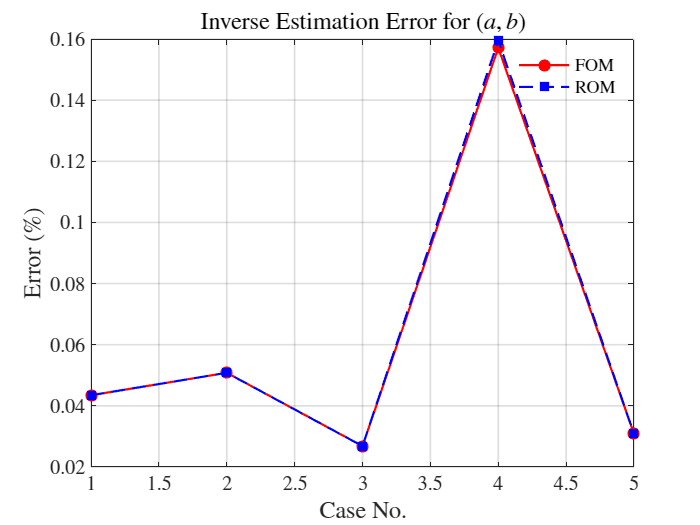


matlab2tikz('Plots/R4f4.tex','width', sprintf('%.2fcm', width),'height', sprintf('%.2fcm', height), 'showInfo', false);

numCases = length(aActual);
% --- Compute 2-norm relative errors for each case ---
errFOM = zeros(1,numCases);
errROM = zeros(1,numCases);

for k = 1:numCases
    diffFOM = [aActual(k) - aCaptureFOM(k), bActual(k) - bCaptureFOM(k)];
    diffROM = [aActual(k) - aCaptureROM(k), bActual(k) - bCaptureROM(k)];
    denom   = [aActual(k), bActual(k)];
    
    errFOM(k) = 100 * norm(diffFOM, 2) / norm(denom, 2);
    errROM(k) = 100 * norm(diffROM, 2) / norm(denom, 2);
end

% --- Plotting the errors ---
figure; hold on; box on;

plot(errFOM, 'ro-', 'LineWidth', 1.3, 'MarkerFaceColor', 'r', ...
    'DisplayName', 'FOM');
plot(errROM, 'bs--', 'LineWidth', 1.3, 'MarkerFaceColor', 'b', ...
    'DisplayName', 'ROM');

xlabel('Case No.', 'Interpreter', 'latex');
ylabel('Error (\%)', 'Interpreter', 'latex');
title('Inverse Estimation Error for $(a,b)$', 'Interpreter', 'latex');

legend('Location', 'northeast', 'Interpreter', 'latex', 'Box', 'off');
grid on;

set(gca, 'FontName', 'Times New Roman', 'FontSize', 12, 'LineWidth', 1);

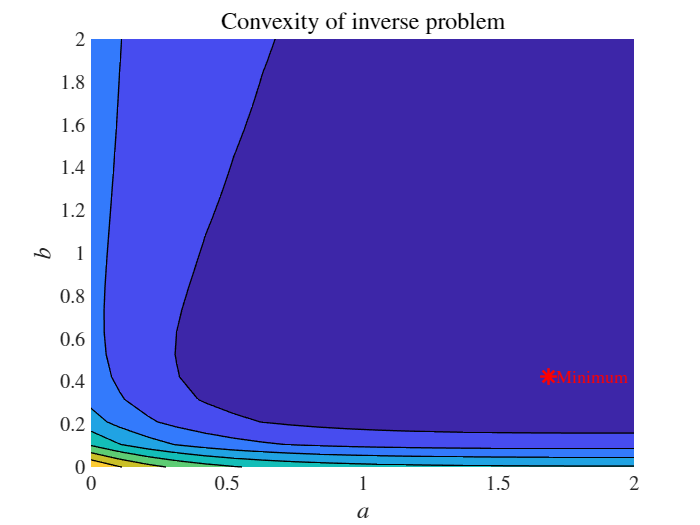



matlab2tikz('Plots/R4f5.tex','width', sprintf('%.2fcm', width),'height', sprintf('%.2fcm', height), 'showInfo', false);

% R4f6
% Convext optimization problem: ROM

aList = linspace(0,2,20);
bList = linspace(0,2,20);
JROM = zeros(length(aList), length(bList));

for i = 1:length(aList)
    for j = 1:length(bList)
        JROM(i,j) = goldenLossROMv4(uFOM(:,end),vFOM(:,end),uBC,vBC,D2,aList(i),bList(j),alpha,beta,Nt,dt,Fu,Fv,x);
    end
end

[A,B] = meshgrid(aList,bList);
figure; hold on; box on;
contourf(A, B, JROM); % filled contours colorbar;
xlabel('$a$', 'Interpreter', 'latex');
ylabel('$b$', 'Interpreter', 'latex');
title('Convexity of inverse problem', 'Interpreter', 'latex');
set(gca, 'FontName', 'Times New Roman', 'FontSize', 12);
grid on;

% Mark minimum
[minVal, idx] = min(JROM(:));
[aMin, bMin] = deal(A(idx), B(idx));
plot(aMin, bMin, 'r*', 'MarkerSize', 10, 'LineWidth', 1.5);
text(aMin+0.02, bMin, 'Minimum', 'Color', 'r', 'FontSize', 11);


matlab2tikz('Plots/R4f6.tex','width', sprintf('%.2fcm', width),'height', sprintf('%.2fcm', height), 'showInfo', false);